% Part D - LQR Controller [run section wise]

%Mass of Crane
Mass_Crane= 1000;

% Mass & Cable length of First Load
mass_1= 100; 
length_1= 20; 
% Mass & Cable length of Second Load
mass_2= 100;
length_2= 10;  
% Gravity component
gravity= 9.81; 

%The A and B matrices of our state space representation are as follows

% A matrix
A= [0 1 0 0 0 0; 
    0 0 -(mass_1*gravity)/Mass_Crane 0 -(mass_2*gravity)/Mass_Crane 0;
    0 0 0 1 0 0;
    0 0 -((Mass_Crane+mass_1)*gravity)/(Mass_Crane*length_1) 0 -(mass_2*gravity)/(Mass_Crane*length_1) 0;
    0 0 0 0 0 1;
    0 0 -(mass_1*gravity)/(Mass_Crane*length_2) 0 -(gravity*(Mass_Crane+mass_2))/(Mass_Crane*length_2) 0];

B = [0; 1/Mass_Crane; 0; 1/(Mass_Crane*length_1); 0; 1/(Mass_Crane*length_2)];

% C matrix is Identity Matrix
C = eye(6);

% D matrix is zeros
D = zeros(6, 1);


% Our state space matrices are
A

A =          0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0    1.0000         0         0
         0         0   -0.5395         0   -0.0491         0
         0         0         0         0         0    1.0000
         0         0   -0.0981         0   -1.0791         0


B

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


C

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D

D =      0
     0
     0
     0
     0
     0


% Controllability

Controllability_matrix =  ctrb(A, B)

Controllability_matrix = 1.0e-03 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0



if (rank(Controllability_matrix)~=6)
    disp("System is Uncontrollable -> Rank of Controllability matrix does not match the Order of A")
    
else
    disp("System is Controllable -> Rank of Controllability matrix is equal to the Order of A")
end

System is Controllable -> Rank of Controllability matrix is equal to the Order of A


% initial conditions 
% distance is in meters and angles is in radians
x_0 = [0.1; 0; -0.19; 0; 0.31; 0]; 

% Compute state space representation using ss function
open_loop_system = ss(A,B,C,D);

rng("default")
%Checking the initial response of the open-loop system
init_plot = initialplot(open_loop_system,x_0)


init_plot =

	resppack.simplot



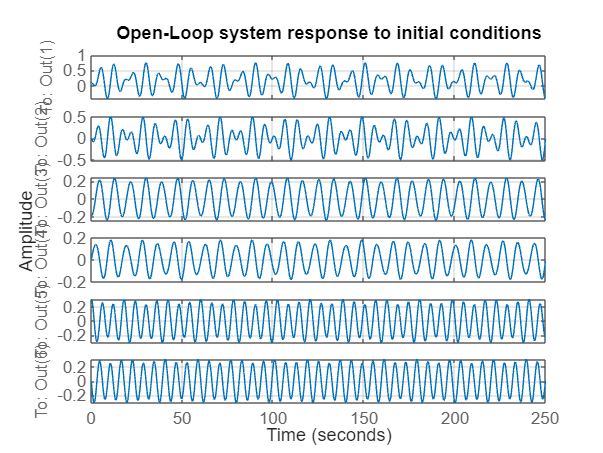

title('Open-Loop system response to initial conditions')

setoptions(init_plot,'TimeUnits','seconds','Grid','on');
setoptions(init_plot, 'XLim',[0 250]);


% LQR controller design [Arbitrary Q and R]

Q = diag([1, 1, 1, 1, 1, 1]);
R = 0.001;

% LQR Gain Matrix
K = lqr(A, B, Q, R);

closed_loop_system = ss(A-(B*K),B,C,D); 
x_0 = [0.1; 0; -0.19; 0; 0.31; 0];

rng("default")

%Checking the initial response of the closed-loop linear system
closed_loop_plot = initialplot(closed_loop_system,x_0)


closed_loop_plot =

	resppack.simplot



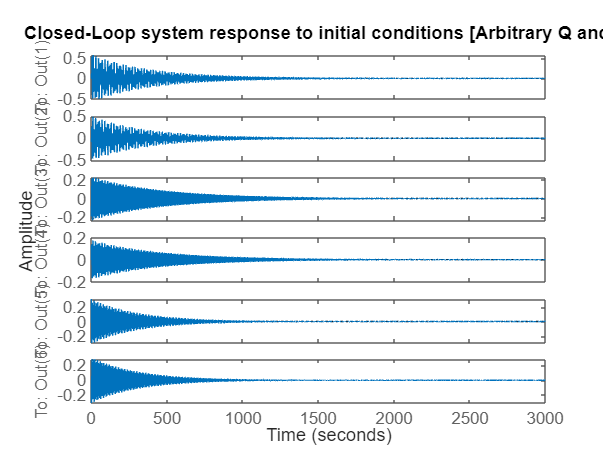

title('Closed-Loop system response to initial conditions [Arbitrary Q and R]')


setoptions(init_plot,'TimeUnits','seconds','Grid','on');

Incorrect number or types of inputs or outputs for function setoptions.

setoptions(init_plot, 'XLim',[0 250]);

% LQR controller design [Arbitrary Q and R]

Q = diag([100, 50, 10, 1, 100, 10]);
R = 0.00001;

% LQR Gain Matrix
K = lqr(A, B, Q, R);

closed_loop_system = ss(A-(B*K),B,C,D); 
x_0 = [0.1; 0; -0.19; 0; 0.31; 0];

rng("default")

%Checking the initial response of the closed-loop linear system
closed_loop_plot = initialplot(closed_loop_system,x_0)
title('Closed-Loop system response to initial conditions [Arbitrary Q and R]')

setoptions(init_plot,'TimeUnits','seconds','Grid','on');
setoptions(init_plot, 'XLim',[0 250]);

% Optimal Q and R on system response

Q = diag([316, 315, 320, 800, 320, 800]);
R = 0.001;

% LQR Gain Matrix
K = lqr(A, B, Q, R);

closed_loop_system = ss(A-(B*K),B,C,D); 
x_0 = [0.1; 0; -0.19; 0; 0.31; 0];

rng("default")

%Checking the initial response of the closed-loop linear system
closed_loop_plot = initialplot(closed_loop_system,x_0)


closed_loop_plot =

	resppack.simplot



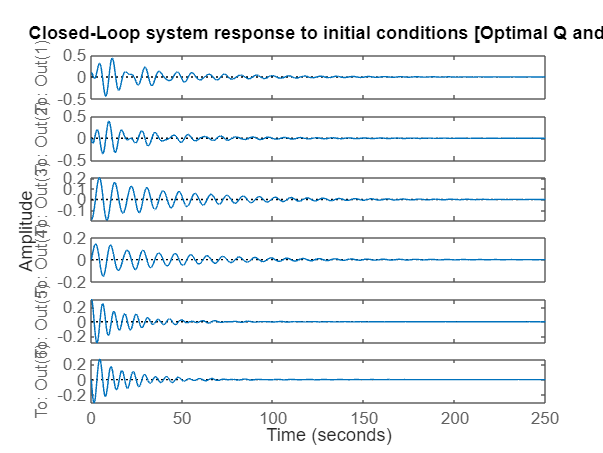

title('Closed-Loop system response to initial conditions [Optimal Q and R]')


setoptions(init_plot,'TimeUnits','seconds','Grid','on');

Incorrect number or types of inputs or outputs for function setoptions.

setoptions(init_plot, 'XLim',[0 250]);

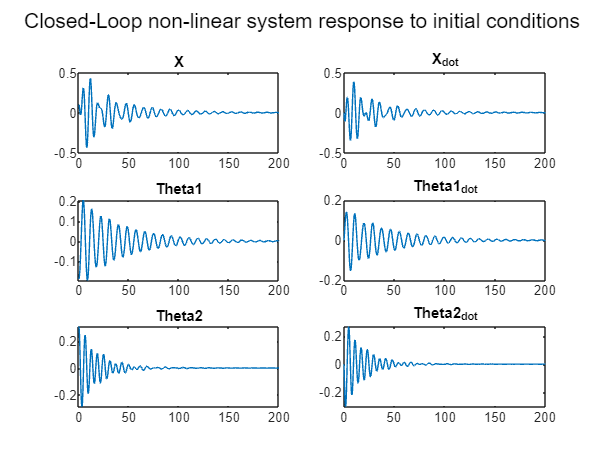

%%Checking the initial response of the closed-loop non-linear system

x_0 = [0.1; 0.0; -0.19; 0.0; 0.31; 0];
% ODE solver for non-linear model
ode_nonlinear = @(t, y) cart_model_non_linear(t, y, K, A, B);
[t_nonlinear, solution_nonlinear] = ode45(ode_nonlinear, [0, 200],x_0 );


figure;

subplot(3, 2, 1);
plot(t_nonlinear, solution_nonlinear(:,1));
title('X');

subplot(3, 2, 2);
plot(t_nonlinear, solution_nonlinear(:,2));
title('X_dot');

subplot(3, 2, 3);
plot(t_nonlinear, solution_nonlinear(:,3));
title('Theta1');

subplot(3, 2, 4);
plot(t_nonlinear, solution_nonlinear(:,4));
title('Theta1_dot');

subplot(3, 2, 5);
plot(t_nonlinear, solution_nonlinear(:,5));
title('Theta2');

subplot(3, 2, 6);
plot(t_nonlinear, solution_nonlinear(:,6));
title('Theta2_dot');

sgtitle('Closed-Loop non-linear system response to initial conditions');

% Lyapunov Indirect Stability Analysis

% Real parts of all eigen values need to be negative inorder for the system
% to be stable
eigen_values = eig(A-B*K)

function dydt = cart_model_non_linear(t, y, K, A, B) % Function to compute non linear dynamics of the system

    % Control Input
    u = K * y;
    

%Mass of Crane
Mass_Crane= 1000;

% Mass & Cable length of First Load
mass_1= 100; 
length_1= 20; 
% Mass & Cable length of Second Load
mass_2= 100;
length_2= 10;  
% Gravity component
gravity= 9.81; 


    % Unpack state variables
    d1 = y(2);
    
    % Compute additional terms for the nonlinear dynamics
    D_D = Mass_Crane + mass_1 + mass_2 - mass_1 * cos(y(3))^2 - mass_2 * cos(y(5))^2;
    term1 = mass_1 * gravity * sin(2 * y(3)) / 2;
    term2 = mass_2 * gravity * sin(2 * y(5)) / 2;
    term3 = mass_1 * length_1 * y(4)^2 * sin(y(3));
    term4 = mass_2 * length_2 * y(6)^2 * sin(y(5));
    
    % Compute state derivatives
    d2 = -(1 / D_D) * (term1 + term2 + term3 + term4 + u);
    d3 = y(4);
    d4 = (1 / length_1) * (d2 * cos(y(3)) - gravity * sin(y(3)));
    d5 = y(6);
    d6 = (1 / length_2) * (d2 * cos(y(5)) - gravity * sin(y(5)));
    
    % Pack state derivatives into a column vector
    dydt = [d1; d2; d3; d4; d5; d6];
end
